# BSP Topic 4: PCA application to analysis of cardiovascular variability signals

**PCA is a useful tool to reduce data dimensionality as this is often an open problem in the context of biomedical signals**

*Project focus: design a procedure for the application of PCA to cardiovascular variability signals*

## 0 - Tools

clc
%clear all
cd C:\Users\aless\SynologyDrive\Documents\PoliMi\Magistrale\1_anno\II_semestre\Signal_processing\Project_work\google_drive\BSP_Project_Work\Building_Blocks
WD = cd;
% Hardcoded variables
fsECG = 300;    % [Hz]

## 1 - Database

% set variables
guarda = 1;
tmin = 60; % [s]
pathSig_AF = strcat(WD, "\1-Database\Code\Data_Categorization\Categories\Training\AF\");
pathSig_N = strcat(WD, "\1-Database\Code\Data_Categorization\Categories\Training\N\");

% atrial fibrillation
type = "_AF";
AFmat = loadsignal (fsECG, pathSig_AF, guarda, tmin, type);

% normal
type = "_N";
Nmat = loadsignal (fsECG, pathSig_N, guarda, tmin, type);

## 2 - Preprocessing

## 2.1 - R peak detection

*Pan-Tompkins implementation*

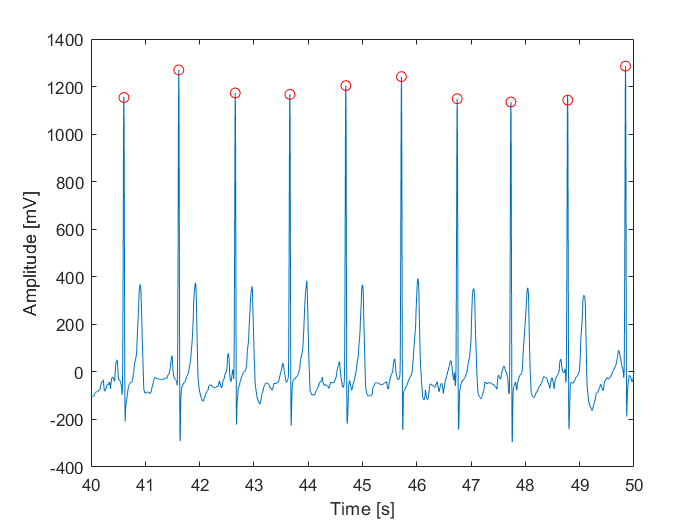

% set PT vars
gr = 0;                                 % no graphs in pan_tompkins
thr = 30;         % mandatory minimum number of beats detected

% set plot vars
graph = 1;      % boolean var (1/0)
patient = 9;    % patient number (row)
type = "N";     % N or AF

% N patients
R_i_N = [];
for i = 1:size(Nmat)
    [~,R_i_V,~]=pan_tompkin(Nmat(i, :),fsECG,gr);
    l = length(R_i_V);
    [m, n] = size(R_i_N);
    if n>l
        R_i_V = [R_i_V zeros(1, n-l)];
    elseif l>n
        R_i_N = [R_i_N zeros(m, l-n)];
    end
    R_i_N = [R_i_N; R_i_V];
end

% AF patients
R_i_AF = [];
for i = 1:size(AFmat)
    [~,R_i_V,~]=pan_tompkin(AFmat(i, :),fsECG,gr);
    l = length(R_i_V);
    [m, n] = size(R_i_AF);
    if n>l
        R_i_V = [R_i_V zeros(1, n-l)];
    elseif l>n
        R_i_AF = [R_i_AF zeros(m, l-n)];
    end
    R_i_AF = [R_i_AF; R_i_V];
end

% checking the results obtained
% checks if a number of beats >= thr was detected
% otherwise it discards the signal

% N
test_thr = sum(R_i_N > 0,2)>thr;
R_i_N = R_i_N(test_thr, :);
Nmat = Nmat(test_thr, :);

% AF
test_thr = sum(R_i_AF > 0,2)>thr;
R_i_AF = R_i_AF(test_thr, :);
AFmat = AFmat(test_thr, :);

% plotting
if graph
    t = 0:1/fsECG:(tmin-1/fsECG);
    if strcmp("N", type)
        figure(1)
        plot(t,Nmat(patient,:))
        hold on
        R_i_V = R_i_N(patient,:);
        R_i_V(R_i_V == 0)=[];
        plot(t(R_i_V+1),Nmat(patient,R_i_V+1), 'ro')
        xlim([40 50])
        hold off
    elseif strcmp("AF", type)
        figure(1)
        plot(t,AFmat(patient,:))
        hold on
        R_i_V = R_i_AF(patient,:);
        R_i_V(R_i_V == 0)=[];
        plot(t(R_i_V),AFmat(patient,R_i_V), 'ro')
        hold off
    end
    xlabel('Time [s]')
    ylabel('Amplitude [mV]')
end

## 2.2 - RR differences

*Creating the RR matrix*

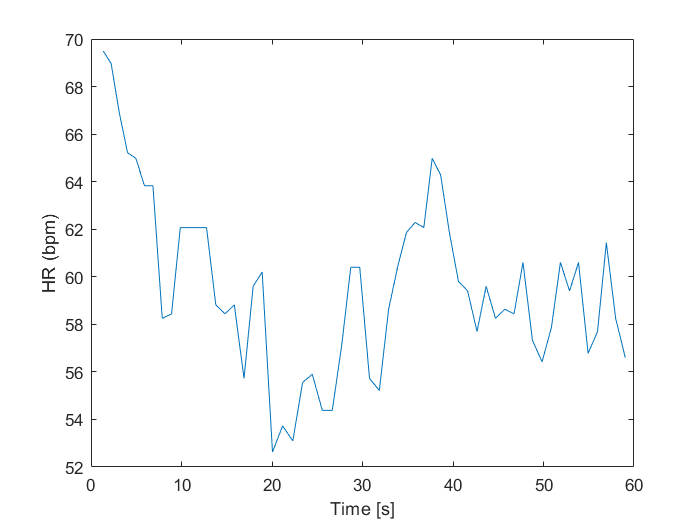

% set plot vars
graph = 1;      % boolean var (1/0)
patient = 9;   % patient number (row)
type = "N";     % N or AF

% N patients
RR_i_N = diff(R_i_N, 1, 2);
RR_i_N(RR_i_N<0) = 0;

% AF patients
RR_i_AF = diff(R_i_AF, 1, 2);
RR_i_AF(RR_i_AF<0) = 0;

% plotting
if graph
    if strcmp("N", type)
        tRR = cleanzeros(R_i_N(patient, 2:end))./fsECG;
        figure(1)
        RR_i_V = cleanzeros(RR_i_N(patient,:));
        plot(tRR,1./RR_i_V*60*fsECG);
    elseif strcmp("AF", type)
        tRR = cleanzeros(R_i_AF(patient, 2:end))./fsECG;
        figure(1)
        RR_i_V = cleanzeros(RR_i_AF(patient,:));
        plot(tRR,1./RR_i_V*60*fsECG);
    end
    xlabel('Time [s]')
    ylabel('HR (bpm)')
end

## 2.3 - Resampling

*Applying Berger's algorithm to reach an equally spaced heart rate*

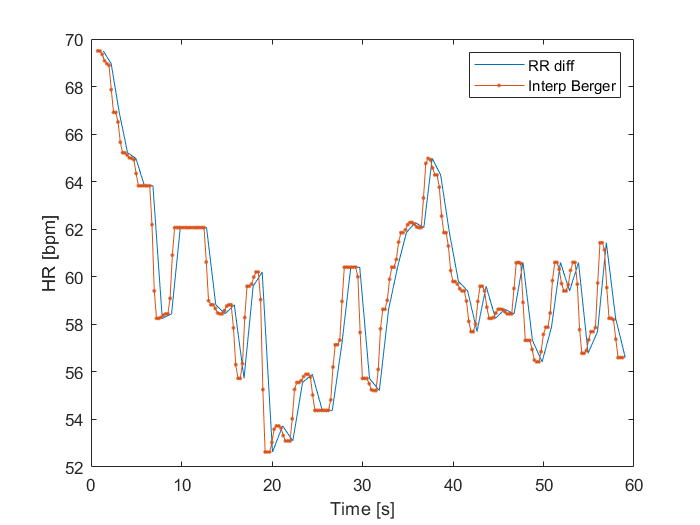

% constants for Berger's algorithm
Frs = 4;        % resampling frequency is 4Hz (128 times less than FsECG)
% WARNING: the ratio between FsECG and Frs MUST be an integer
w = 2;          % width of the window is 2 samples in the Frs scale

% set plot vars
graph = 1;      % boolean var (1/0)
patient = 9;    % patient number (row)
type = "N";    % N or AF

% N patients
ri_i_N = [];
for i = 1:size(R_i_N)
    R = cleanzeros(R_i_N(i,:));
    ri_i_V = berger (R, w, Frs, fsECG);
    l = length(ri_i_V);
    [m, n] = size(ri_i_N);
    if n>l
        ri_i_V = [ri_i_V zeros(1, n-l)];
    elseif l>n
        ri_i_N = [ri_i_N zeros(m, l-n)];
    end
    ri_i_N = [ri_i_N; ri_i_V];
end

% AF patients
ri_i_AF = [];
for i = 1:size(R_i_AF)
    R = cleanzeros(R_i_AF(i,:));
    ri_i_V = berger (R, w, Frs, fsECG);
    l = length(ri_i_V);
    [m, n] = size(ri_i_AF);
    if n>l
        ri_i_V = [ri_i_V zeros(1, n-l)];
    elseif l>n
        ri_i_AF = [ri_i_AF zeros(m, l-n)];
    end
    ri_i_AF = [ri_i_AF; ri_i_V];
end

% plot
graph = 1;
if graph
    if strcmp("N", type)
        figure(1)
        tR = cleanzeros(R_i_N(patient, 1:end))./fsECG;
        RR_i_V = cleanzeros(RR_i_N(patient,:));
        plot(tR(2:end),1./RR_i_V*60*fsECG);
        hold on
        tri = tR(1):1/Frs:tR(end);
        ri_i_V = cleanzeros(ri_i_N(patient,:));
        plot(tri(2:end-1), ri_i_V*60, 'LineStyle',"-", 'Marker',".")
        %xlim([40 50])
        hold off
    elseif strcmp("AF", type)
        figure(1)
        tR = cleanzeros(R_i_AF(patient, 1:end))./fsECG;
        RR_i_V = cleanzeros(RR_i_AF(patient,:));
        plot(tR(2:end),1./RR_i_V*60*fsECG);
        hold on
        tri = tR(1):1/Frs:tR(end);
        ri_i_V = cleanzeros(ri_i_AF(patient,:));
        plot(tri(2:end-1), ri_i_V*60, 'LineStyle',"-", 'Marker',".")
        hold off
    end
    xlabel('Time [s]')
    ylabel('HR [bpm]')
    legend('RR diff', 'Interp Berger');
end

## 3 - Heart Rate Variability (HRV)

## 3.1 - Time-domain analysis

*Extracting HRV variables in the time domain*

% set vars


Header = {'meanRR','meanHR','range','SDNN','RMSSD','NN50','pNN50', 'HRV_t_i'};

% N patients
TD_N = [];
for i = 1:size(RR_i_N)
    RR = cleanzeros(RR_i_N(i,:));
    [meanRR_V, meanHR_V, range_V, SDNN_V, RMSSD_V, NN50_V, pNN50_V, HRVti_V] = timeDomain(RR, fsECG);
    TD_N = [TD_N; [meanRR_V, meanHR_V, range_V, SDNN_V, RMSSD_V, NN50_V, pNN50_V, HRVti_V]];
end
T_TD_N = array2table(TD_N, 'VariableNames', Header);

%AF patients
TD_AF = [];
for i = 1:size(RR_i_AF)
    RR = cleanzeros(RR_i_AF(i,:));
    [meanRR_V, meanHR_V, range_V, SDNN_V, RMSSD_V, NN50_V, pNN50_V, HRVti_V] = timeDomain(RR, fsECG);
    TD_AF = [TD_AF; [meanRR_V, meanHR_V, range_V, SDNN_V, RMSSD_V, NN50_V, pNN50_V, HRVti_V]];
end

T_TD_AF = array2table(TD_AF, 'VariableNames', Header);

## 3.2 - Frequency-domain analysis

*Extracting HRV variables in the frequency domain*

% Parameters for the  parametric methods and Welch's method
ORDER=8;                   % order of the autoregressive models

Header = {'VLF','LF','HF','LF_HF_ratio','tot_pow'};

% N patients
FD_N = [];
for i = 1:size(ri_i_N)
    ri= cleanzeros(ri_i_N(i,:));
    [VLF_V, LF_V, HF_V, LF_HF_V, tot_pow_V] = frequencyDomain(ri,Frs,ORDER);
    FD_N = [FD_N; [VLF_V, LF_V, HF_V, LF_HF_V, tot_pow_V]];
end
T_FD_N = array2table(FD_N, 'VariableNames', Header);

% AF patients
FD_AF = [];
for i = 1:size(ri_i_AF)
    ri= cleanzeros(ri_i_AF(i,:));
    [VLF_V, LF_V, HF_V, LF_HF_V, tot_pow_V] = frequencyDomain(ri,Frs,ORDER);
    FD_AF = [FD_AF; [VLF_V, LF_V, HF_V, LF_HF_V, tot_pow_V]];
end
T_FD_AF = array2table(FD_AF, 'VariableNames', Header);

## 4- Principal Component Analysis (PCA)

## 4.1 - Normalizing the data

% all patients
norm_DS = zscore([TD_N FD_N; TD_AF FD_AF]); % normalized database

## 4.2 - Calculating the covariance matrix

% covariance
C = cov(norm_DS);

## 4.3 - Calulating the eigenvalues and eigenvectors of the covariance matrix

% W eigenvectors | Lambda: eigenvalues
[W, Lambda] = eig(C);
% placing the components in descending order
%Lambda = flip(Lambda);              % mirror horizontally
%Lambda = flip (Lambda, 2);          % mirror vertically
%W = flip(W);                        % mirror vertically

## 4.4 - Performing SVD decomposition

% all patients
[U, Sigma, V]=svd(norm_DS);

## 4.5 - Derive the new dataset

% pick the number of principal components to be used
p = 2;
% Choose p components and form the features vector
Vp = V(:,1:p);

% Derive the new dataset
new_DS = norm_DS*Vp;

## 4.6 - Visualizing the result

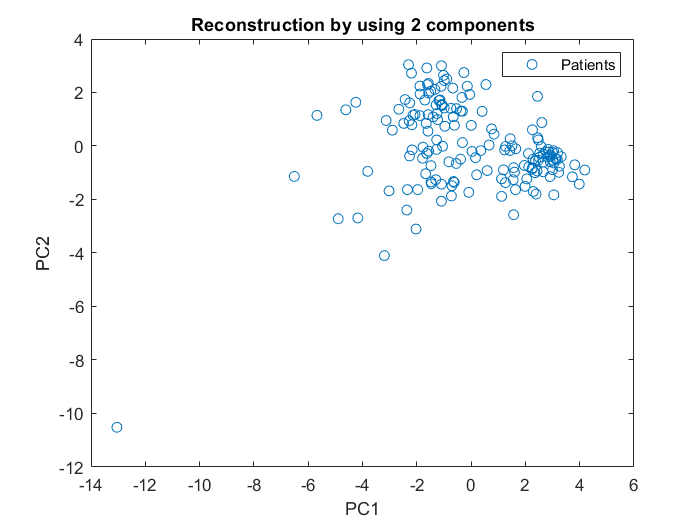

% visualize results
figure (1)
plot(new_DS(:,1), new_DS(:,2),'o');
xlabel('PC1');
ylabel('PC2');
legend('Patients');
title('Reconstruction by using 2 components');

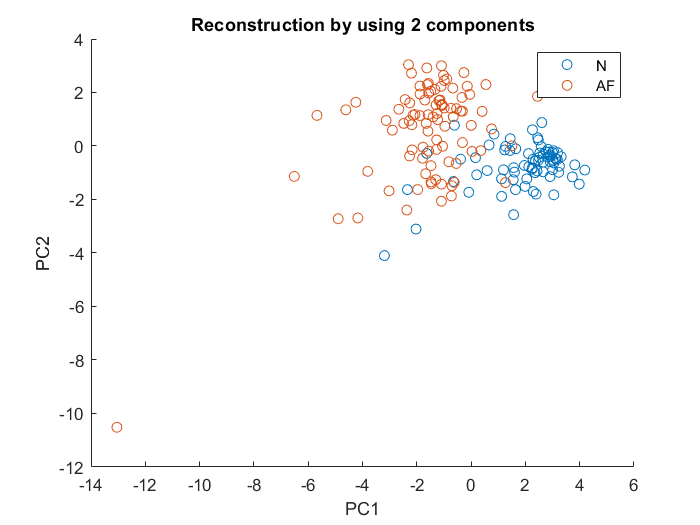

figure(2)
scatter(new_DS(1:size(Nmat,1),1), new_DS(1:size(Nmat,1),2));
hold on
scatter(new_DS(size(Nmat,1)+1:end,1), new_DS(size(Nmat,1)+1:end,2));
xlabel('PC1');
ylabel('PC2');
title('Reconstruction by using 2 components');
legend('N', 'AF')

%corrplot(norm_DS)

% visualize single feature
DS = [TD_N FD_N; TD_AF FD_AF]; % normalized database

scatter(zeros(size(Nmat,1),1),DS(1:size(Nmat,1),6))
hold on
scatter(ones(size(AFmat,1),1),DS(end-size(AFmat,1)+1:end,6))
xlim([-2 3])
yline(-0.25)

## Classification of AF and N conditions using PCA and Neural Networks 

% Saving the first two PRINCIPAL COMPONENTS for classification
% VARIABLES=new_DS'; 
% LABELS=[ones(1,75) zeros(1,92);zeros(1,75) ones(1,92)];

% Or just load the variables already saved..
load('NNInputs.mat')
j=0;
% In the following code there are trained 100 NN and from them is selected
% the one with the highest validation score and lowest error calculated from the training phase 

for i=1:100
    j=j+1;
    net = patternnet(i); 
    [net,param] = train(net,VARIABLES,LABELS);
    NET.(['n' num2str(j)])=net;
    PARAM.(['n' num2str(j)])=param.testInd;
    y = net(VARIABLES);
    [cn,cm] = confusion(LABELS,y);
    Por(j)=(100*(1-cn));
    per(j)=perform(net,LABELS,y);
    [M,I]=min(per);
    POR(j)=Por(I);
end
subplot(2,1,1);plot(Por); % RECOGNITION scores in training phase
title('Percentage of RECOGNITION in TRAINING phase')
subplot(2,1,2);plot(per); % Error scores
title('Percentage of ERROR in TRAINING phase')
% Calculation of Percentage of recognition in each of the samples of the VALIDATION SET 
% using the best NN of the trainig phase

for j=1:25 %# of samples employed in the test phase
    var=PARAM.(['n' num2str(I)]);
    r(:,j)=sim(NET.(['n' num2str(I)]),VARIABLES(:,var(j))); 
end

%% Confusion matrix associated to the samples used for validation
VAR=VARIABLES(:,var);
LAB=LABELS(:,var);
y = net(VAR);
[cn,cm] = confusion(LAB,y); %Final Confusion matrix